**DIG DEMO**

- Load the data. In this case EEG measures (rows - channels, columns - observations)


data = load('n10_8-12hz');
data = data.data;
labels = load('labelsn10.mat');
labels = labels.hyp;

**DIG applied with the default parameters, in this case 'L' = 3840, since the labeling for sleep stages is given in this time lapse. **

[Y, z_hist] = DIG(data(4:8,:), 'L',3840);

Computing distances among time-windows of data
Computing Affinity Matrix
Diffusing operator
Computing potential/gamma/inf_geometry distances
using -log(P) potential distance
MDS


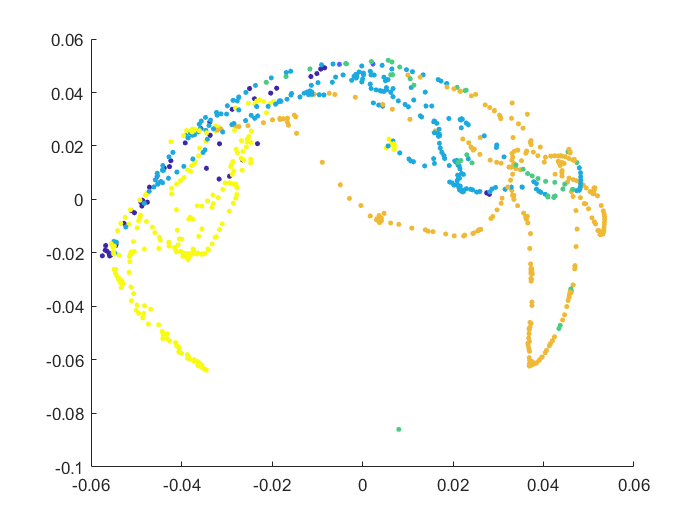

scatter(Y(:,1), Y(:,2), 10, labels, 'filled');

**Trying different values for 'L2' to compute the covariance matrices. L2 = 5 produces a noisy embedding, while L2 = 100, smooths everything out. We are gonna stay with L2 = 20.   **

Computing distances among time-windows of data
Computing Affinity Matrix
Diffusing operator
Computing potential/gamma/inf_geometry distances
using information geometry distance (arccos)
MDS


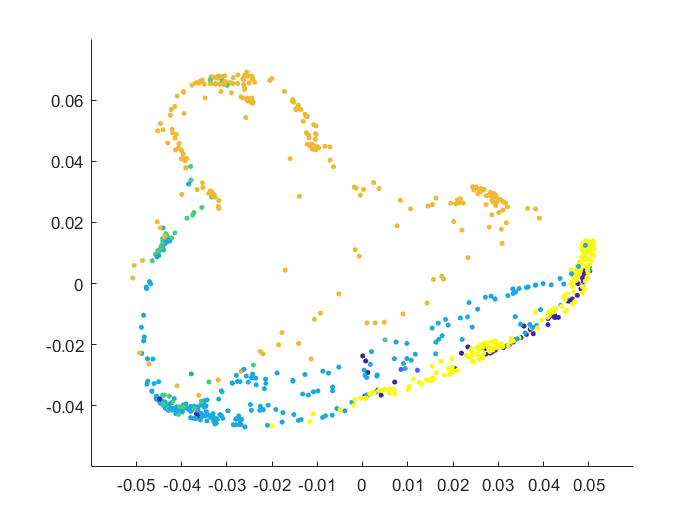

Computing distances among time-windows of data
Computing Affinity Matrix
Diffusing operator
Computing potential/gamma/inf_geometry distances
using information geometry distance (arccos)
MDS


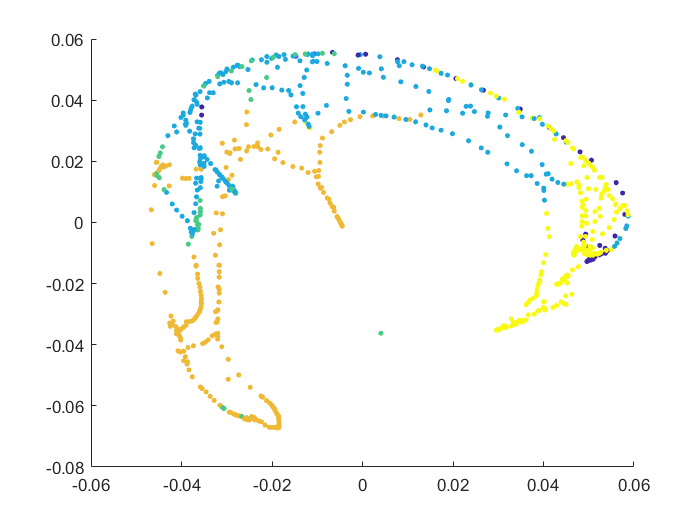

Computing distances among time-windows of data
Computing Affinity Matrix
Diffusing operator
Computing potential/gamma/inf_geometry distances
using information geometry distance (arccos)
MDS


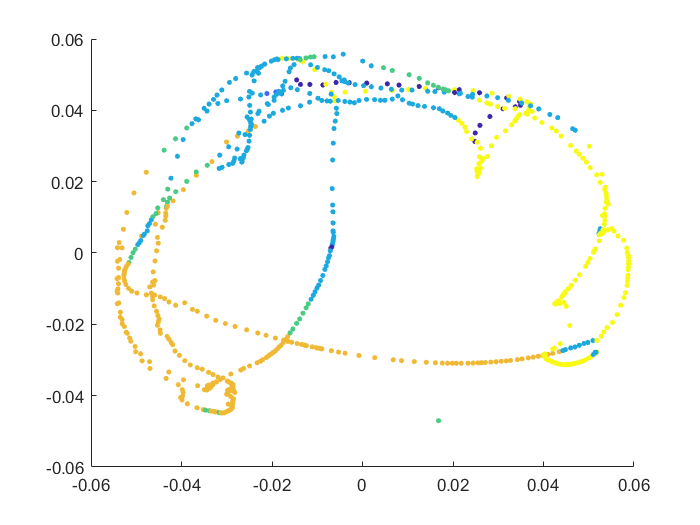

Computing distances among time-windows of data
Computing Affinity Matrix
Diffusing operator
Computing potential/gamma/inf_geometry distances
using information geometry distance (arccos)
MDS


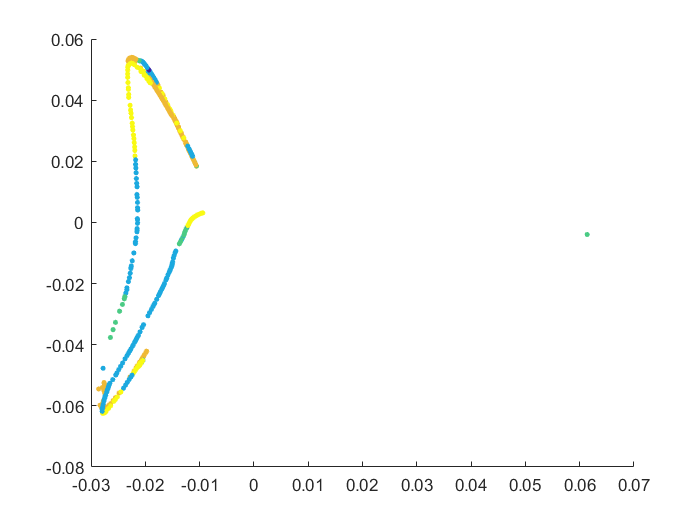

L2v = [5, 20, 40, 100];
for L2 = L2v
[Y, z_hist] = DIG(data(4:10,:), 'L',3840, 'L2', L2, 'pot_method', 'info_geometry');
figure
scatter(Y(:,1), Y(:,2), 10, labels, 'filled');
drawnow
end 

**Now let's take a look to the different distances in the potential operator, we can see that the information geometry distance is quite similar to the Hellinger distance figures 1 and 3.**

Computing distances among time-windows of data
Computing Affinity Matrix
Diffusing operator
Computing potential/gamma/inf_geometry distances
using information geometry distance (arccos)
MDS


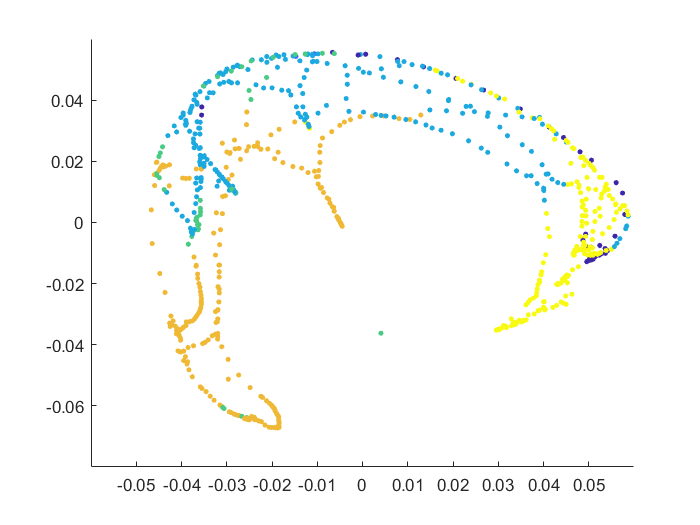

Computing distances among time-windows of data


Computing Affinity Matrix
Diffusing operator
Computing potential/gamma/inf_geometry distances
MDS


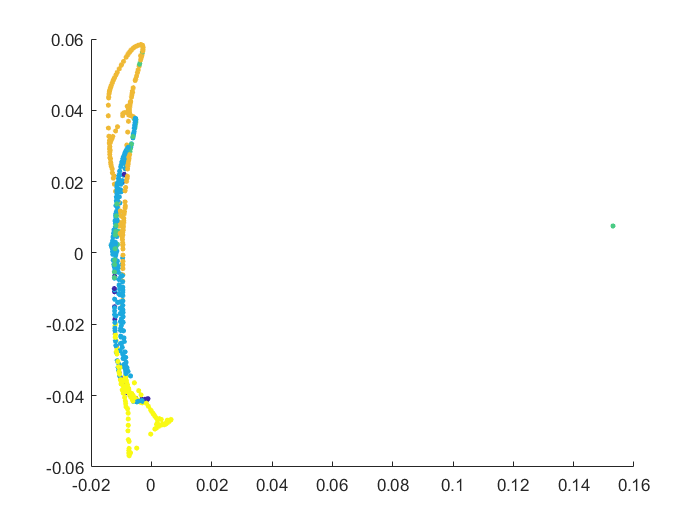

Computing distances among time-windows of data
Computing Affinity Matrix
Diffusing operator
Computing potential/gamma/inf_geometry distances
using sqrt(P) potential distance
MDS


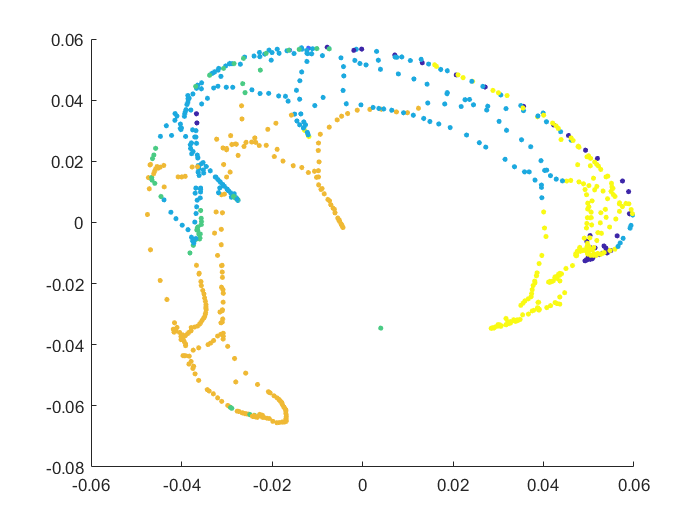

Computing distances among time-windows of data
Computing Affinity Matrix
Diffusing operator
Computing potential/gamma/inf_geometry distances
using -log(P) potential distance
MDS


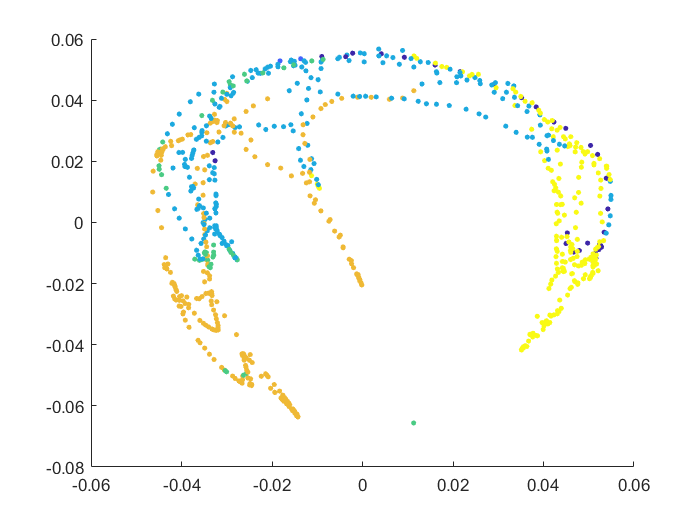

potMethods = ["info_geometry", "none", "sqrt", "log"];
for potM = potMethods
[Y, z_hist] = DIG(data(4:10,:), 'L',3840, 'L2', 20, 'pot_method', potM);
figure
scatter(Y(:,1), Y(:,2), 10, labels, 'filled');
drawnow
end 

**Different values of gamma **

Computing distances among time-windows of data
Computing Affinity Matrix
Diffusing operator
Computing potential/gamma/inf_geometry distances
MDS


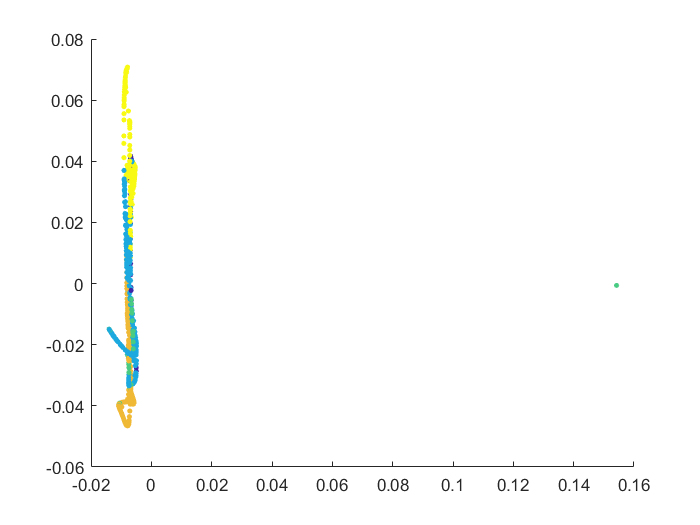

Computing distances among time-windows of data
Computing Affinity Matrix
Diffusing operator
Computing potential/gamma/inf_geometry distances
Pot = 2/(1-\gamma)*P^((1-\gamma)/2)
gamma = -0.6
MDS


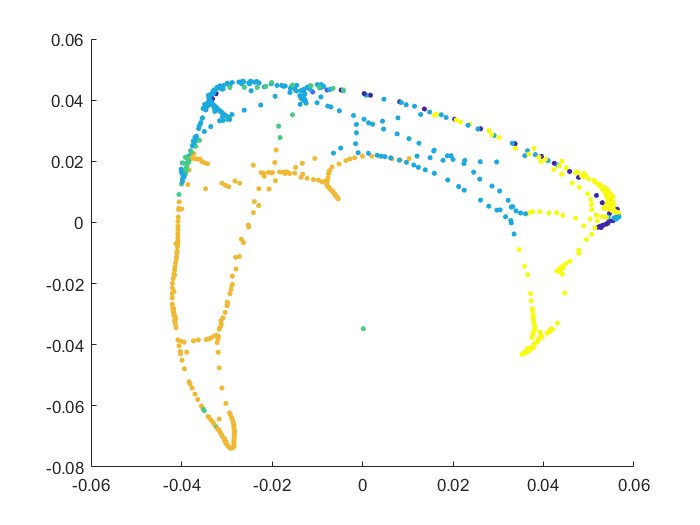

Computing distances among time-windows of data
Computing Affinity Matrix
Diffusing operator
Computing potential/gamma/inf_geometry distances
Pot = 2/(1-\gamma)*P^((1-\gamma)/2)
gamma = -0.2
MDS


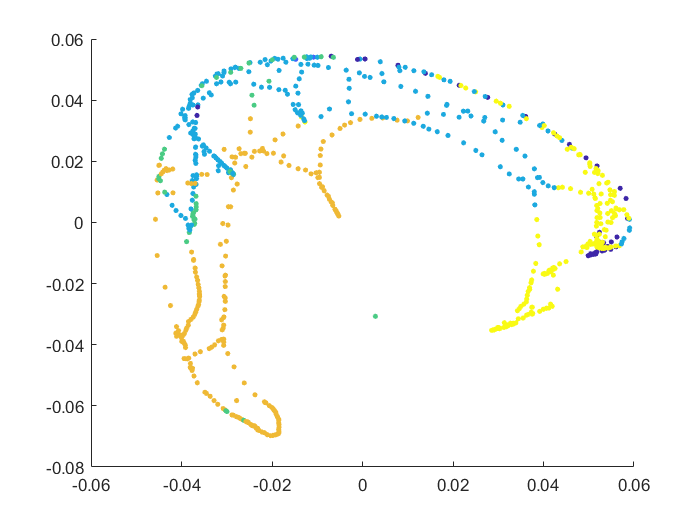

Computing distances among time-windows of data
Computing Affinity Matrix
Diffusing operator
Computing potential/gamma/inf_geometry distances
Pot = 2/(1-\gamma)*P^((1-\gamma)/2)
gamma = 0.2
MDS


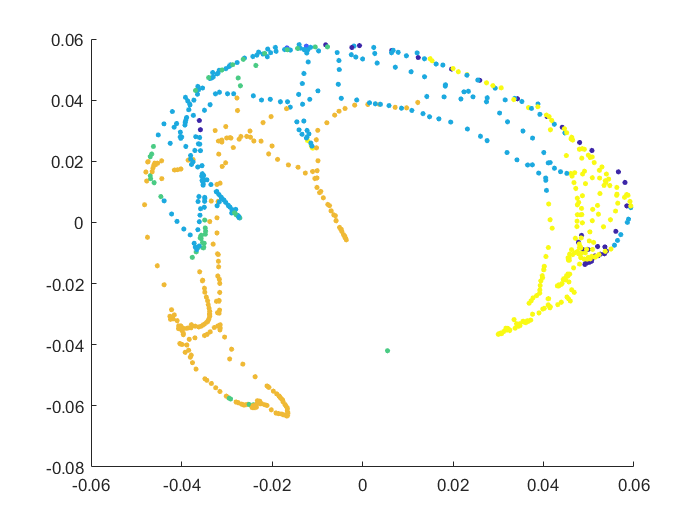

Computing distances among time-windows of data
Computing Affinity Matrix
Diffusing operator
Computing potential/gamma/inf_geometry distances
Pot = 2/(1-\gamma)*P^((1-\gamma)/2)
gamma = 0.6
MDS


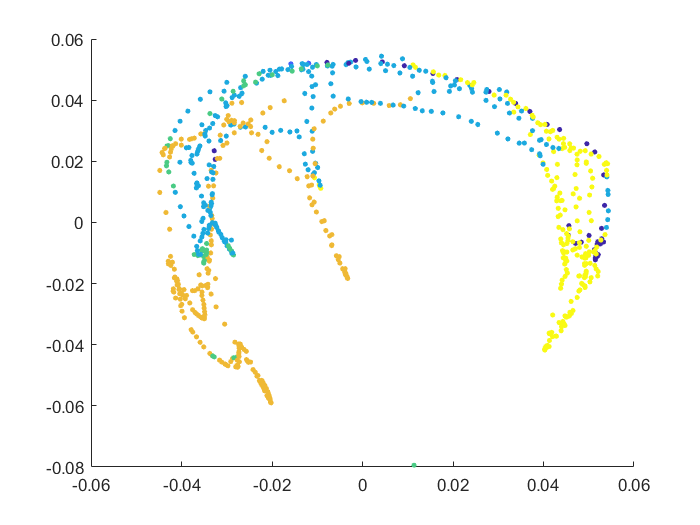

Computing distances among time-windows of data
Computing Affinity Matrix
Diffusing operator
Computing potential/gamma/inf_geometry distances
MDS


Gammas = [-1:0.4:1];
for gamma_v = Gammas
[Y, z_hist] = DIG(data(4:10,:), 'L',3840, 'L2', 20, 'pot_method', 'gamma', 'Gamma', gamma_v);
figure
scatter(Y(:,1), Y(:,2), 10, labels, 'filled');
drawnow
end 

**Instead of computing the EIG distance, we can also compute the KL divergence or the infomarion geometry distances between time windows of data, assuming a multivariate normal distribution. We can see that altough we can distingish between different sleep stages, the embeddings are noisier than for the EIG distance. **

Computing distances among time-windows of data
Using information geometry distance, make sure the data is approximatly Mul. Gaussian with 0 mean
Computing Affinity Matrix
Diffusing operator
Computing potential/gamma/inf_geometry distances
Pot = 2/(1-\gamma)*P^((1-\gamma)/2)
gamma = 0
MDS


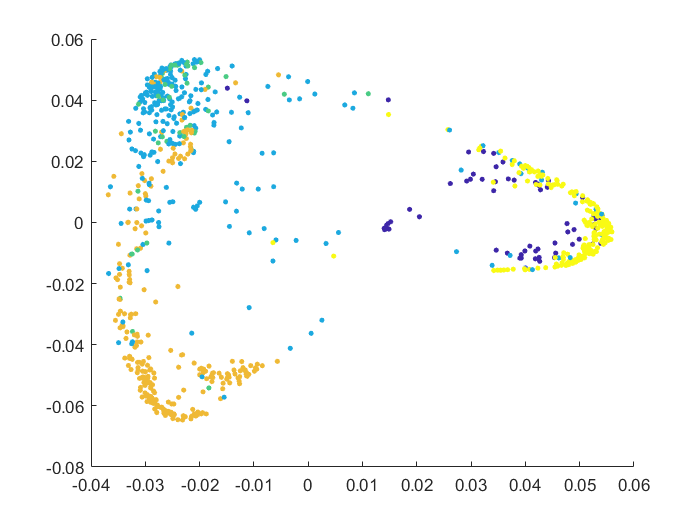

Computing distances among time-windows of data
Using Kullback-Liebler divergence, make sure the data is approximatly Mul. Gaussian with 0 mean
Computing Affinity Matrix
Diffusing operator
Computing potential/gamma/inf_geometry distances
Pot = 2/(1-\gamma)*P^((1-\gamma)/2)
gamma = 0
MDS


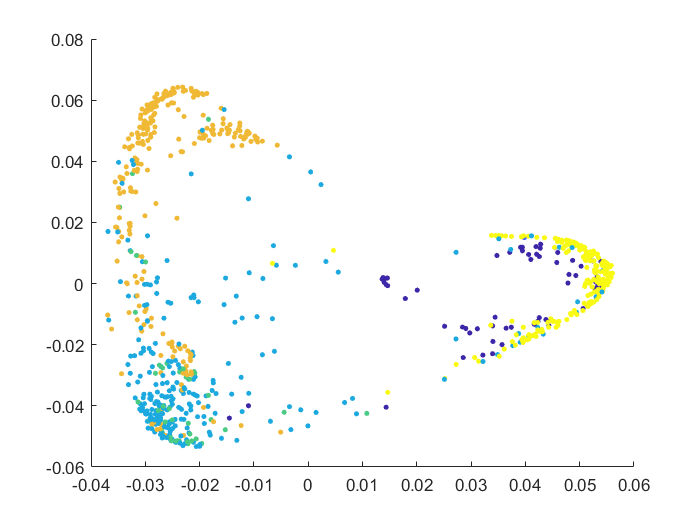

sD_v = ["InfGeo","KL"];
for sD = sD_v
[Y, z_hist] = DIG(data(4:10,:), 'L',3840, 'L2', 20, 'pot_method', 'gamma', 'Gamma', 0, 'series_distance', sD);
figure
scatter(Y(:,1), Y(:,2), 10, labels, 'filled');
drawnow
end 

**Finally we can choose different values of t and alpha. **

Computing distances among time-windows of data
Computing Affinity Matrix
Diffusing operator
Computing potential/gamma/inf_geometry distances
Pot = 2/(1-\gamma)*P^((1-\gamma)/2)
gamma = 0
MDS


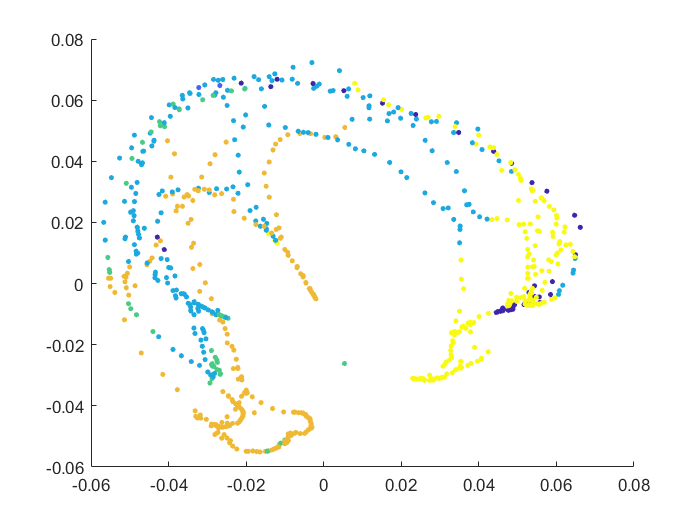

Computing distances among time-windows of data
Computing Affinity Matrix
Diffusing operator
Computing potential/gamma/inf_geometry distances
Pot = 2/(1-\gamma)*P^((1-\gamma)/2)
gamma = 0
MDS


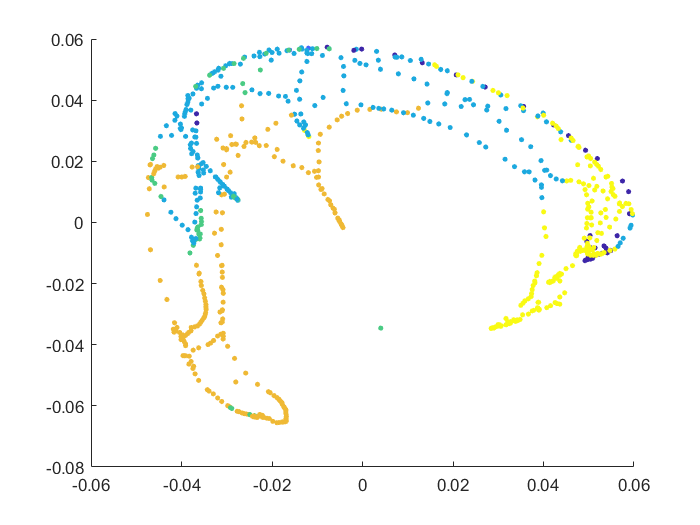

Computing distances among time-windows of data
Computing Affinity Matrix
Diffusing operator
Computing potential/gamma/inf_geometry distances
Pot = 2/(1-\gamma)*P^((1-\gamma)/2)
gamma = 0
MDS


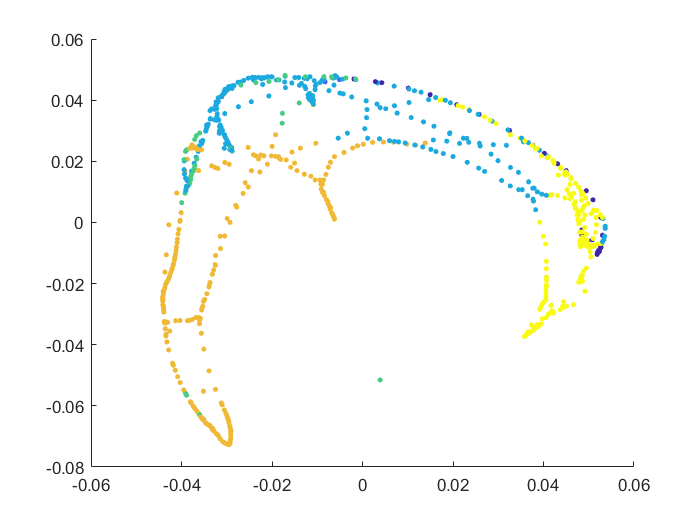

Computing distances among time-windows of data
Computing Affinity Matrix
Diffusing operator
Computing potential/gamma/inf_geometry distances
Pot = 2/(1-\gamma)*P^((1-\gamma)/2)
gamma = 0
MDS


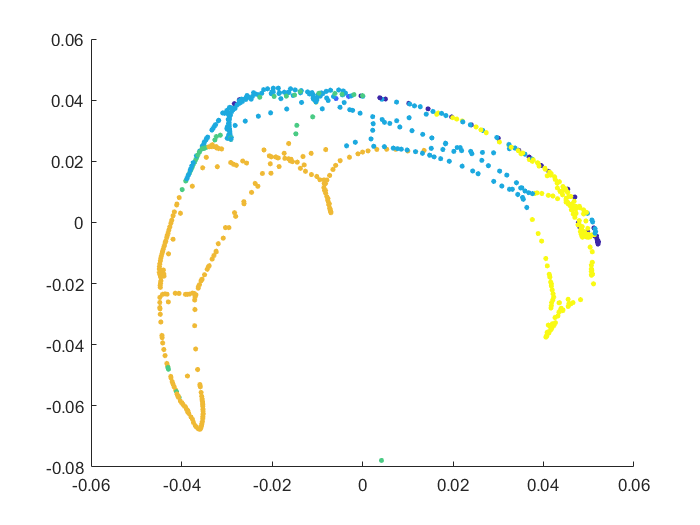

Computing distances among time-windows of data
Computing Affinity Matrix
Diffusing operator
Computing potential/gamma/inf_geometry distances
Pot = 2/(1-\gamma)*P^((1-\gamma)/2)
gamma = 0
MDS


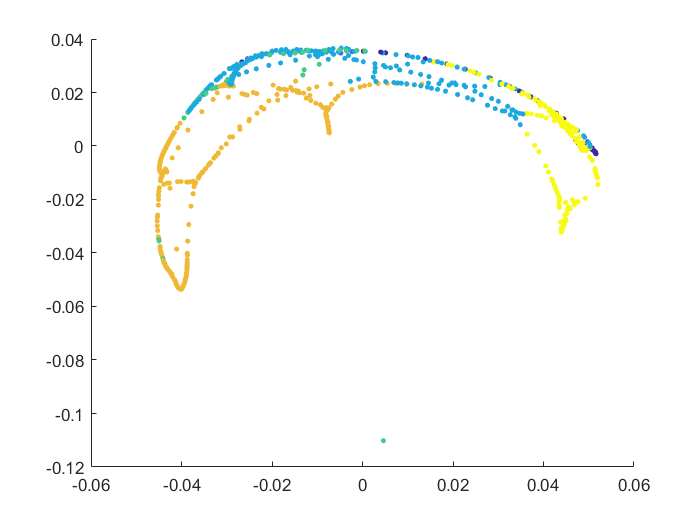

t_v = [5, 10, 20, 30, 40];
for tv = t_v
[Y, z_hist] = DIG(data(4:10,:), 'L',3840, 'L2', 20, 'pot_method', 'gamma', 'Gamma', 0, 't', tv);
figure
scatter(Y(:,1), Y(:,2), 10, labels, 'filled');
drawnow
end 

Computing distances among time-windows of data
Computing Affinity Matrix
Diffusing operator
Computing potential/gamma/inf_geometry distances
Pot = 2/(1-\gamma)*P^((1-\gamma)/2)
gamma = 0
MDS


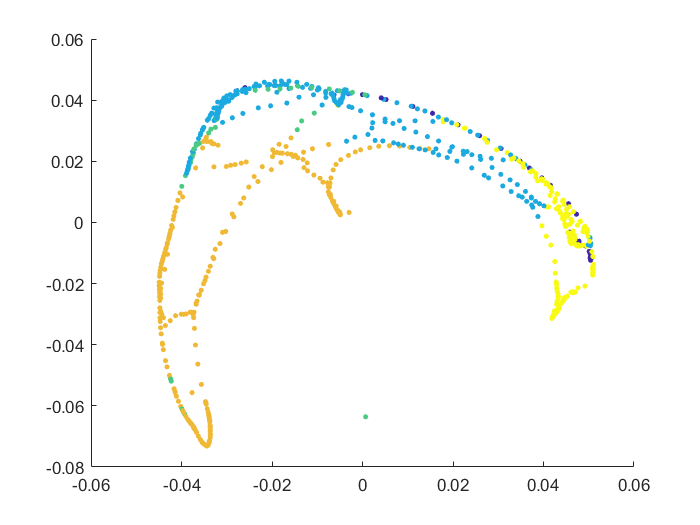

Computing distances among time-windows of data
Computing Affinity Matrix
Diffusing operator
Computing potential/gamma/inf_geometry distances
Pot = 2/(1-\gamma)*P^((1-\gamma)/2)
gamma = 0
MDS


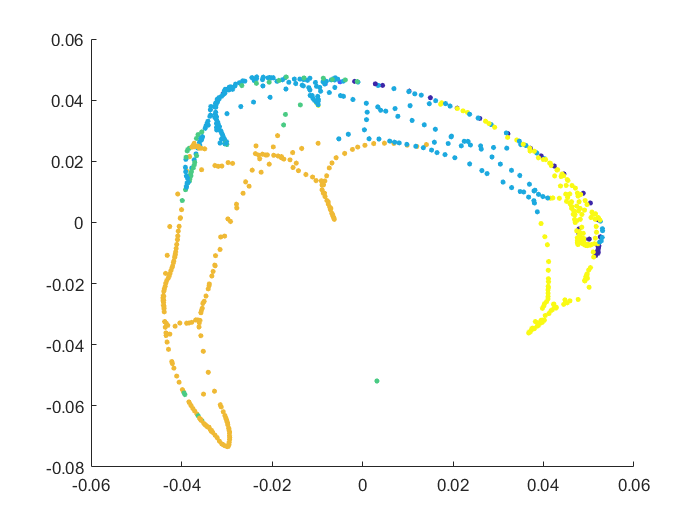

Computing distances among time-windows of data
Computing Affinity Matrix
Diffusing operator
Computing potential/gamma/inf_geometry distances
Pot = 2/(1-\gamma)*P^((1-\gamma)/2)
gamma = 0
MDS


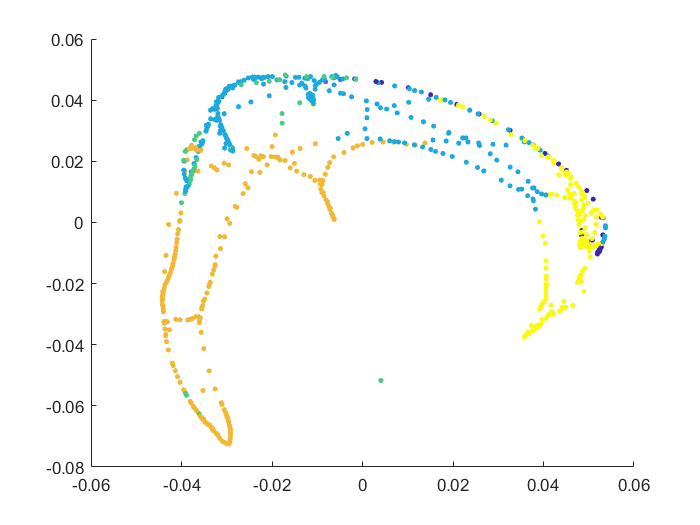

Computing distances among time-windows of data
Computing Affinity Matrix
Diffusing operator
Computing potential/gamma/inf_geometry distances
Pot = 2/(1-\gamma)*P^((1-\gamma)/2)
gamma = 0
MDS


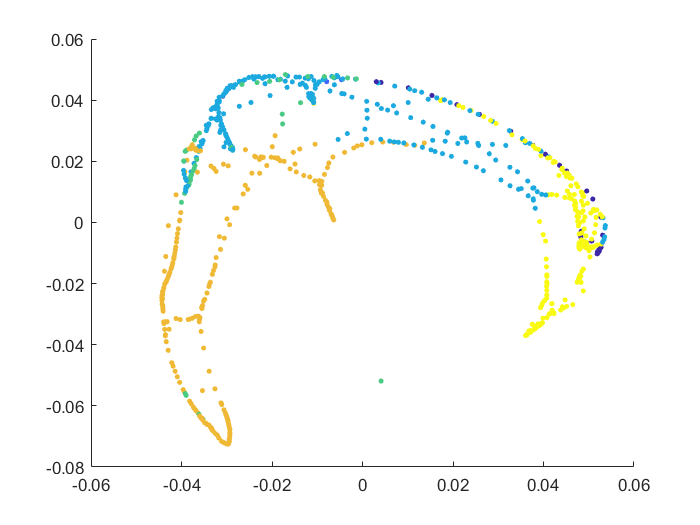

Computing distances among time-windows of data
Computing Affinity Matrix
Diffusing operator
Computing potential/gamma/inf_geometry distances
Pot = 2/(1-\gamma)*P^((1-\gamma)/2)
gamma = 0
MDS


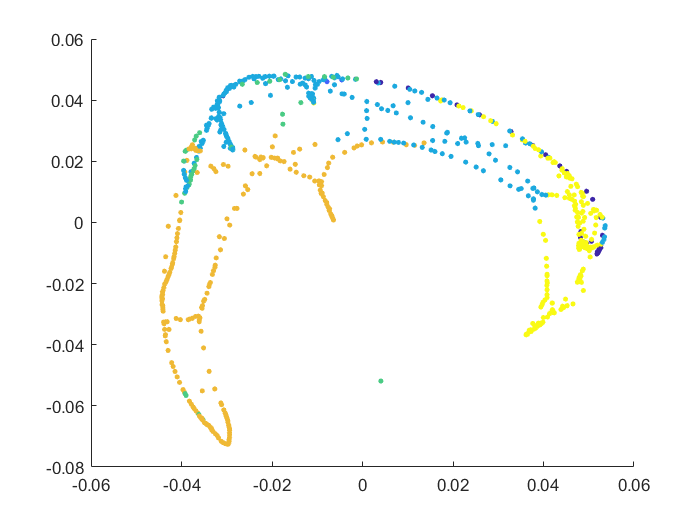

a_v = [2, 5, 15, 30, 40];
for av = a_v
[Y, z_hist] = DIG(data(4:10,:), 'L',3840, 'L2', 20, 'pot_method', 'gamma', 'Gamma', 0, 't', 20, 'a', av);
figure
scatter(Y(:,1), Y(:,2), 10, labels, 'filled');
drawnow
end 